%% UR3 + własne TCP + chwytak + workspace
clear; clc; close all;

%% 1. Wczytanie robota

robot = loadrobot("universalUR3", ...
    "DataFormat","row", ... 
    "Gravity",[0 0 -9.81]);

disp("Body names:");

Body names:


disp(robot.BodyNames');

    {'base_link'     }
    {'base'          }
    {'shoulder_link' }
    {'upper_arm_link'}
    {'forearm_link'  }
    {'wrist_1_link'  }
    {'wrist_2_link'  }
    {'wrist_3_link'  }
    {'ee_link'       }
    {'tool0'         }




% Konfiguracja testowa
q = [0 -pi/2 0 0 -pi/2 0];

%% 2. Nazwa członu, do którego dodajemy narzędzie

parentBodyName = "tool0";

if ~any(strcmp(robot.BodyNames, parentBodyName))
    warning("Nie znaleziono body '%s'. Używam ostatniego body w modelu.", parentBodyName);
    parentBodyName = robot.BodyNames{end};
end

fprintf("Narzędzie zostanie dodane do body: %s\n", parentBodyName);

Narzędzie zostanie dodane do body: tool0



%% 3. Dane TCP względem flanszy/tool0

% Dane do wpisania w pendant UR:
% X  =    0 mm
% Y  = -290 mm
% Z  =  260 mm
% RX = 0
% RY = 0
% RZ = 0

tcp_x =  0.000;
tcp_y = -0.290;
tcp_z =  0.260;

tcp_rx = 0;
tcp_ry = 0;
tcp_rz = 0;

%% 4. Wymiary chwytaka [m]

% ---------------------------------------------------------
% Belka pionowa
% ---------------------------------------------------------
beam_len  = 0.31;       % 31 cm
beam_side = 0.015;      % 1.5 cm x 1.5 cm

% Pręt
rod_len    = 0.25;      % 25 cm
rod_radius = 0.003;     % średnica 0.6 cm -> promień 0.3 cm

% Wysokość mocowania pręta na belce
% Mierzone od dołu belki.
rod_height_from_bottom = 0.29;   % 29 cm od dołu belki

% Z tego wynika, że nad prętem zostaje:
attach_from_top = beam_len - rod_height_from_bottom;

fprintf("Pręt wychodzi %.1f cm poniżej górnego końca belki.\n", attach_from_top*100);

Pręt wychodzi 2.0 cm poniżej górnego końca belki.


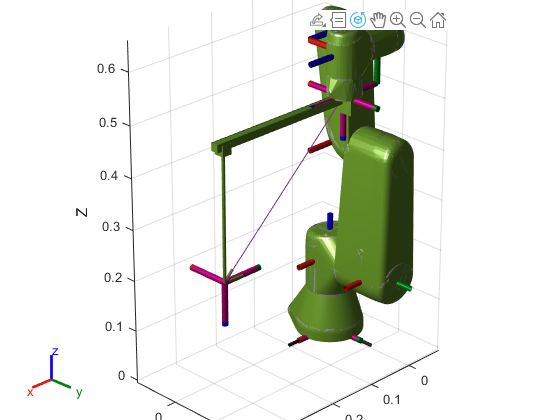


% Widły
fork_len        = 0.035;     % 3.5 cm
fork_gap        = 0.030;     % rozstaw końcówek 3 cm
fork_width      = 0.004;     % szerokość jednej szczęki
fork_thick      = 0.004;     % grubość jednej szczęki
fork_tilt_deg   = 15;        % pochylenie wideł

% Bloczek przy flanszy
flange_block_thick = 0.020;  % 2 cm
flange_block_side  = 0.055;  % przyjęte pomocniczo 5.5 cm

% Bloczek 90 stopni belka-pręt
joint_block_side = 0.020;    % 2 cm

%% 5. Transformacja flansza -> TCP

% Orientacja TCP jest zerowa, więc wystarczy translacja.
% Gdybyś kiedyś miał niezerowe RX RY RZ, trzeba złożyć rotację z wektora rotacji.
T_flange_tcp = trvec2tform([tcp_x tcp_y tcp_z]);

%% 6. Utworzenie body narzędzia

tool = rigidBody("custom_tcp");
toolJoint = rigidBodyJoint("custom_tcp_fixed","fixed");

setFixedTransform(toolJoint, T_flange_tcp);
tool.Joint = toolJoint;

%% 7. Geometria chwytaka względem TCP

% =========================================================
% Przyjęty lokalny układ TCP:
%
% - TCP jest na końcu pręta, przy mocowaniu wideł.
% - Pręt idzie od TCP do belki w kierunku lokalnym -Z.
% - Widły idą zasadniczo w dół, czyli w kierunku lokalnym +Y.
% - Belka jest pionowa, jej długość jest w osi lokalnej Y.
% - Pręt wychodzi z belki 29 cm od dołu, czyli 2 cm od góry.
%
% Wszystkie collision obiekty są definiowane względem custom_tcp.
% =========================================================

%% 7.1 Pręt

% Punkt końca pręta przy belce, liczony względem TCP.
p_rod_start_tcp = [0 0 -rod_len];

% Cylinder jest domyślnie wzdłuż osi Z.
% Środek pręta jest w połowie długości między TCP a belką.
T_rod = trvec2tform([0 0 -rod_len/2]);

rodCollision = collisionCylinder(rod_radius, rod_len);
addCollision(tool, rodCollision, T_rod);

%% 7.2 Belka pionowa

% Chcemy, żeby pręt wychodził z przedniej ścianki belki.
% Lokalny punkt mocowania na belce względem jej środka:
%
% y = -beam_len/2 + attach_from_top
% ponieważ góra belki jest przy y = -beam_len/2,
% a pręt jest attach_from_top poniżej góry.
%
% z = +beam_side/2
% czyli przednia ścianka belki, od strony TCP.

p_attach_beam_local = [ ...
    0, ...
   -beam_len/2 + attach_from_top, ...
    beam_side/2];

% Szukamy środka belki tak, aby punkt mocowania pokrył się
% z początkiem pręta.
p_beam_center_tcp = p_rod_start_tcp - p_attach_beam_local;

T_beam = trvec2tform(p_beam_center_tcp);

beamCollision = collisionBox(beam_side, beam_len, beam_side);
addCollision(tool, beamCollision, T_beam);

%% 7.3 Bloczek 90 stopni na połączeniu belka-pręt

% Mały bloczek w miejscu wyjścia pręta z belki.
% To jest uproszczona reprezentacja połączenia 90 stopni.
T_joint_block = trvec2tform(p_rod_start_tcp);

jointBlockCollision = collisionBox(joint_block_side, joint_block_side, joint_block_side);
addCollision(tool, jointBlockCollision, T_joint_block);

%% 7.4 Bloczek przy flanszy

% Ponieważ custom_tcp jest odsunięty od tool0 o [tcp_x tcp_y tcp_z],
% położenie flanszy względem TCP to w przybliżeniu:
p_flange_tcp = [-tcp_x, -tcp_y, -tcp_z];

% Uproszczony bloczek przy flanszy.
% Jeżeli przeszkadza w wizualizacji/kolizjach, można go zakomentować.
T_flange_block = trvec2tform(p_flange_tcp);

flangeBlockCollision = collisionBox(flange_block_side, flange_block_thick, flange_block_side);
addCollision(tool, flangeBlockCollision, T_flange_block);

%% 7.5 Widły

% Widły mają kształt V.
% Rozwarcie końcówek wynosi fork_gap.
% Długość każdej szczęki wynosi fork_len.

% Kąt rozwarcia jednej szczęki względem osi środkowej.
fork_open = atan((fork_gap/2) / fork_len);

% Pochylenie wideł.
% Jeżeli w wizualizacji pochylą się w złą stronę,
% zmień znak przy fork_tilt_deg.
fork_tilt = deg2rad(-fork_tilt_deg);

R_tilt = axang2tform([1 0 0 fork_tilt]);

R_open_left  = axang2tform([0 0 1  fork_open]);
R_open_right = axang2tform([0 0 1 -fork_open]);

% Jedna szczęka jako cienki box.
% Długość boxa jest w osi Y.
forkCollision = collisionBox(fork_width, fork_len, fork_thick);

% Środek szczęki jest w połowie długości od TCP.
T_fork_left = R_tilt * R_open_left * trvec2tform([0, fork_len/2, 0]);
addCollision(tool, forkCollision, T_fork_left);

T_fork_right = R_tilt * R_open_right * trvec2tform([0, fork_len/2, 0]);
addCollision(tool, forkCollision, T_fork_right);

%% 8. Dodanie narzędzia do robota

addBody(robot, tool, parentBodyName);

%% 9. Wizualizacja robota z chwytakiem

figure('Color','w');
show(robot, q, ...
    "Frames","on", ...
    "Collisions","on", ...
    "Visuals","on");

axis equal;
grid on;
view(135, 25);
title("UR3 z własnym TCP i modelem chwytaka");

exportgraphics(gcf, "model_UR3_chwytak.png", "Resolution", 300);


%% 10. Wydruk TCP do teach pendanta

tcp_xyz_m = tform2trvec(T_flange_tcp);

R_flange_tcp = tform2rotm(T_flange_tcp);
axang = rotm2axang(R_flange_tcp);

% UR używa wektora rotacji:
% [rx ry rz] = oś * kąt
tcp_rvec_rad = axang(1:3) * axang(4);

fprintf("\n========================================\n");

fprintf("TCP do wpisania w UR / PolyScope\n");

TCP do wpisania w UR / PolyScope


fprintf("========================================\n");


fprintf("Format URScript:\n");

Format URScript:


fprintf("p[%.6f, %.6f, %.6f, %.6f, %.6f, %.6f]\n", ...
    tcp_xyz_m(1), tcp_xyz_m(2), tcp_xyz_m(3), ...
    tcp_rvec_rad(1), tcp_rvec_rad(2), tcp_rvec_rad(3));

p[0.000000, -0.290000, 0.260000, 0.000000, 0.000000, 0.000000]



fprintf("\nPozycja w milimetrach:\n");


Pozycja w milimetrach:


fprintf("X  = %.1f mm\n", tcp_xyz_m(1)*1000);

X  = 0.0 mm


fprintf("Y  = %.1f mm\n", tcp_xyz_m(2)*1000);

Y  = -290.0 mm


fprintf("Z  = %.1f mm\n", tcp_xyz_m(3)*1000);

Z  = 260.0 mm



fprintf("\nRotacja jako wektor rotacji:\n");


Rotacja jako wektor rotacji:


fprintf("RX = %.6f rad\n", tcp_rvec_rad(1));

RX = 0.000000 rad


fprintf("RY = %.6f rad\n", tcp_rvec_rad(2));

RY = 0.000000 rad


fprintf("RZ = %.6f rad\n", tcp_rvec_rad(3));

RZ = 0.000000 rad



%% 11. Odczyt pozycji TCP względem base dla konfiguracji q

T_base_tcp = getTransform(robot, q, "custom_tcp");

disp("Transformacja base -> custom_tcp:");

Transformacja base -> custom_tcp:


disp(T_base_tcp);

    0.0000   -1.0000    0.0000    0.3754
   -1.0000    0.0000    0.0000    0.1124
   -0.0000   -0.0000   -1.0000    0.2669
         0         0         0    1.0000




tcp_position_base = tform2trvec(T_base_tcp);

disp("Pozycja TCP względem base [m]:");

Pozycja TCP względem base [m]:


disp(tcp_position_base);

    0.3754    0.1124    0.2669




%% 12. Test kolizji

[isColliding, sepDist, witnessPts] = checkCollision(robot, q, ...
    "IgnoreSelfCollision","on");

fprintf("Czy wykryto kolizję? %d\n", isColliding);

Czy wykryto kolizję? 0



%% 13. Punkty charakterystyczne chwytaka względem TCP

% Końce wideł w lokalnych układach boxów.
% Box szczęki ma długość fork_len w osi Y,
% więc koniec szczęki jest w +fork_len/2 od środka boxa.

p_left_tip_localBox  = [0; fork_len/2; 0; 1];
p_right_tip_localBox = [0; fork_len/2; 0; 1];

% Końce wideł względem TCP
p_left_tip_tcp  = T_fork_left  * p_left_tip_localBox;
p_right_tip_tcp = T_fork_right * p_right_tip_localBox;

% Środek między końcówkami wideł
p_center_tip_tcp = 0.5 * (p_left_tip_tcp + p_right_tip_tcp);

disp("Koniec lewej szczęki względem TCP [m]:");

Koniec lewej szczęki względem TCP [m]:


disp(p_left_tip_tcp(1:3).');

   -0.0138    0.0311   -0.0083




disp("Koniec prawej szczęki względem TCP [m]:");

Koniec prawej szczęki względem TCP [m]:


disp(p_right_tip_tcp(1:3).');

    0.0138    0.0311   -0.0083




disp("Środek końcówek wideł względem TCP [m]:");

Środek końcówek wideł względem TCP [m]:


disp(p_center_tip_tcp(1:3).');

         0    0.0311   -0.0083




%% 14. Numeryczny obszar roboczy chwytaka

% Liczba próbek:
% 5000  - szybki podgląd
% 20000 - sensowny wynik
% 50000 - ładniej do dokumentacji, ale wolniej
N = 100000;

% Czy sprawdzać kolizje przy każdej próbce?
% true  - wolniej, ale odrzuca konfiguracje kolizyjne
% false - szybciej, pokazuje czysty zasięg kinematyczny
useCollisionFilter = false;

pts_tcp    = zeros(N,3);
pts_center = zeros(N,3);
pts_left   = zeros(N,3);
pts_right  = zeros(N,3);

valid = false(N,1);

for i = 1:N

    qk = randomConfiguration(robot);

    if useCollisionFilter
        isCollidingSample = checkCollision(robot, qk, ...
            "IgnoreSelfCollision","on");

        if isCollidingSample
            continue;
        end
    end

    T_base_tcp_k = getTransform(robot, qk, "custom_tcp");

    % TCP
    pts_tcp(i,:) = tform2trvec(T_base_tcp_k);

    % Środek końcówek wideł
    p_center_base = T_base_tcp_k * p_center_tip_tcp;
    pts_center(i,:) = p_center_base(1:3).';

    % Lewa końcówka
    p_left_base = T_base_tcp_k * p_left_tip_tcp;
    pts_left(i,:) = p_left_base(1:3).';

    % Prawa końcówka
    p_right_base = T_base_tcp_k * p_right_tip_tcp;
    pts_right(i,:) = p_right_base(1:3).';

    valid(i) = true;
end

pts_tcp    = pts_tcp(valid,:);
pts_center = pts_center(valid,:);
pts_left   = pts_left(valid,:);
pts_right  = pts_right(valid,:);

fprintf("\nLiczba poprawnych próbek workspace: %d\n", size(pts_center,1));


Liczba poprawnych próbek workspace: 100000



%% Maksymalna przybliżona średnica obszaru roboczego

% =========================================================
% Średnica obszaru roboczego = największa odległość między
% dwoma punktami z chmury workspace.
%
% Używamy punktów środka końcówek chwytaka: pts_center.
% =========================================================

fprintf("\n========================================\n");

fprintf("Przybliżona średnica obszaru roboczego\n");

Przybliżona średnica obszaru roboczego


fprintf("========================================\n");


% Żeby nie liczyć wszystkich odległości dla bardzo dużego N,
% wybieramy maksymalnie M punktów losowo.
M = 5000;

numPts = size(pts_center, 1);

if numPts > M
    idx = randperm(numPts, M);
    pts_diam = pts_center(idx, :);
else
    pts_diam = pts_center;
end

% Macierz odległości między punktami
D = pdist2(pts_diam, pts_diam);

% Maksymalna odległość
[max_diameter_m, linearIdx] = max(D(:));

% Indeksy dwóch najbardziej oddalonych punktów
[iMax, jMax] = ind2sub(size(D), linearIdx);

p1 = pts_diam(iMax, :);
p2 = pts_diam(jMax, :);

fprintf("Przybliżona maksymalna średnica workspace:\n");

Przybliżona maksymalna średnica workspace:


fprintf("%.4f m\n", max_diameter_m);

1.8711 m



fprintf("\nCzyli w milimetrach:\n");


Czyli w milimetrach:


fprintf("%.1f mm\n", max_diameter_m * 1000);

1871.1 mm



fprintf("\nPunkt 1 [m]: X = %.3f, Y = %.3f, Z = %.3f\n", p1(1), p1(2), p1(3));


Punkt 1 [m]: X = 0.406, Y = 0.220, Z = 0.964


fprintf("Punkt 2 [m]: X = %.3f, Y = %.3f, Z = %.3f\n", p2(1), p2(2), p2(3));

Punkt 2 [m]: X = -0.415, Y = -0.253, Z = -0.650


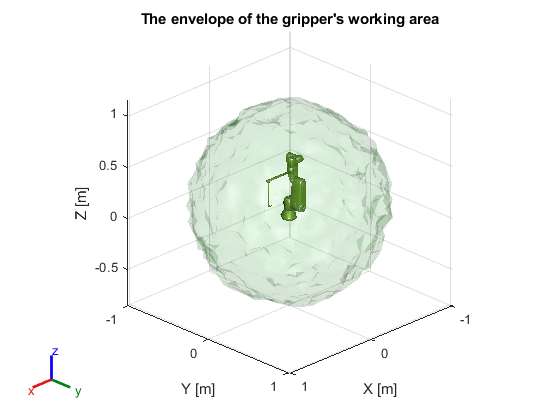


try
    % ---------------------------------------------
    % 1. Obwiednia obszaru roboczego
    % ---------------------------------------------
    % 1.0 -> bardziej wypukła
    % 0.8 -> dobry kompromis
    % 0.6 -> bardziej dopasowana
    shrinkFactor = 0.8;

    K = boundary(pts_center(:,1), pts_center(:,2), pts_center(:,3), shrinkFactor);

    % ---------------------------------------------
    % 2. Środek obszaru roboczego
    % ---------------------------------------------
    workspace_center = mean(pts_center, 1);

    % Promień małej kulki w środku obszaru
    centerSphereRadius = 0.04;   % 4 cm, możesz zmienić

    [sx, sy, sz] = sphere(30);
    sx = centerSphereRadius * sx + workspace_center(1);
    sy = centerSphereRadius * sy + workspace_center(2);
    sz = centerSphereRadius * sz + workspace_center(3);

    % ---------------------------------------------
    % 3. Utworzenie wykresu
    % ---------------------------------------------
    figure('Color','w');
    ax = axes;
    hold(ax, 'on');

    % Najpierw robot z chwytakiem
    % Visuals = model UR3
    % Collisions = widoczna geometria chwytaka (i ewentualnie kolizje robota)
    show(robot, q, ...
        "Parent", ax, ...
        "Frames", "off", ...
        "Visuals", "on", ...
        "Collisions", "on", ...
        "PreservePlot", false);

    hold(ax, 'on');

    % ---------------------------------------------
    % 4. Zewnętrzna obwiednia workspace
    % ---------------------------------------------
    hHull = trisurf(K, ...
        pts_center(:,1), pts_center(:,2), pts_center(:,3), ...
        'Parent', ax, ...
        'FaceColor', [0.3 0.8 0.3], ...
        'FaceAlpha', 0.10, ...
        'EdgeColor', 'none');

    % ---------------------------------------------
    % 5. Środek workspace jako mała półprzezroczysta kula
    % ---------------------------------------------
    hCenter = surf(ax, sx, sy, sz, ...
        'FaceColor', [0.1 0.7 0.1], ...
        'FaceAlpha', 0.30, ...
        'EdgeColor', 'none');

    % Dodatkowo punkt środka
    plot3(ax, workspace_center(1), workspace_center(2), workspace_center(3), ...
        'o', ...
        'MarkerSize', 8, ...
        'MarkerFaceColor', [0 0.5 0], ...
        'MarkerEdgeColor', 'k');

    % ---------------------------------------------
    % 6. Oświetlenie i wygląd
    % ---------------------------------------------
    axis(ax, 'equal');
    grid(ax, 'on');
    xlabel(ax, 'X [m]');
    ylabel(ax, 'Y [m]');
    zlabel(ax, 'Z [m]');
    title(ax, "The envelope of the gripper's working area");

    view(ax, 135, 25);
    camlight(ax, 'headlight');
    lighting(ax, 'gouraud');

    % ---------------------------------------------
    % 7. Automatyczne limity osi z zapasem
    % ---------------------------------------------
    x_all = pts_center(:,1);
    y_all = pts_center(:,2);
    z_all = pts_center(:,3);

    % dodaj też środek i okolice robota
    x_all = [x_all; workspace_center(1); 0];
    y_all = [y_all; workspace_center(2); 0];
    z_all = [z_all; workspace_center(3); 0];

    pad = 0.10;  % 10 cm zapasu

    xlim(ax, [min(x_all)-pad, max(x_all)+pad]);
    ylim(ax, [min(y_all)-pad, max(y_all)+pad]);
    zlim(ax, [min(z_all)-pad, max(z_all)+pad]);

    % ---------------------------------------------
    % 8. Opcjonalnie: delikatnie wyłącz clipping
    % ---------------------------------------------
    ax.Clipping = 'off';

    % ---------------------------------------------
    % 9. Zapis do pliku
    % ---------------------------------------------
    exportgraphics(gcf, "workspace_obwiednia_robot_srodek.png", "Resolution", 300);

catch ME
    warning("Nie udało się narysować obwiedni workspace: %s", E.message);
end

clear; clc; close all;

% Test_pól
%% TEST BOARD DELTAS

P_A1 = [-165 -715 25];
P_H1 = [ 225 -708 25];
P_A8 = [-165 -330 21];
P_H8 = [ 211 -317 19];

squareCenter = @(fileIdx, rankIdx) ...
    (1-fileIdx/7)*(1-rankIdx/7)*P_A1 + ...
    (fileIdx/7)*(1-rankIdx/7)*P_H1 + ...
    (1-fileIdx/7)*(rankIdx/7)*P_A8 + ...
    (fileIdx/7)*(rankIdx/7)*P_H8;

C_A1 = squareCenter(0,0);
C_B1 = squareCenter(1,0);
C_A2 = squareCenter(0,1);
C_B2 = squareCenter(1,1);
C_D5 = squareCenter(3,4);

disp("C_A1 = "); disp(C_A1);

C_A1 = 
  -165  -715    25



disp("C_B1 = "); disp(C_B1);

C_B1 = 
 -109.2857 -714.0000   25.0000



disp("C_A2 = "); disp(C_A2);

C_A2 = 
 -165.0000 -660.0000   24.4286



disp("C_B2 = "); disp(C_B2);

C_B2 = 
 -109.5714 -658.8776   24.3878



disp("C_D5 = "); disp(C_D5);

C_D5 = 
   -1.2857 -490.5306   22.2245




disp("Delta A1 -> B1 = "); disp(C_B1 - C_A1);

Delta A1 -> B1 = 
   55.7143    1.0000         0



disp("Delta A1 -> A2 = "); disp(C_A2 - C_A1);

Delta A1 -> A2 = 
         0   55.0000   -0.5714



disp("Delta A1 -> B2 = "); disp(C_B2 - C_A1);

Delta A1 -> B2 = 
   55.4286   56.1224   -0.6122



disp("Delta A1 -> D5 - [165 220 0] = "); disp(C_D5 - C_A1 - [165 220 0]);

Delta A1 -> D5 - [165 220 0] = 
   -1.2857    4.4694   -2.7755

